# MIMO Simulation at 28 GHz in an Indoor Environment

### Ozlem Yildiz    zy2043    

### Ufuk Usubutun    uu2001

## Data Loading

load roomPathData.mat

rxPos = pathData.rxPos;
nrxPos = size(rxPos, 1);

txPos = pathData.txPos; 

npaths = pathData.npaths;
linkState = pathData.linkState;


% RX position selection random
i_rx = randi(nrxPos);

fc = pathData.fc;

%Angels

aoaAz = pathData.aoaAz(i_rx, :)';
aoaEl = pathData.aoaEl(i_rx, :)';
aodAz = pathData.aodAz(i_rx, :)';
aodEl = pathData.aodEl(i_rx, :)';

pl = pathData.pl(i_rx, :); 
dly = pathData.dly(i_rx,:)';
gain = pathData.gain(i_rx,:)';

posStep = pathData.posStep;

## Data Demonstration

Parameters are from 'indoorDataDemo' 

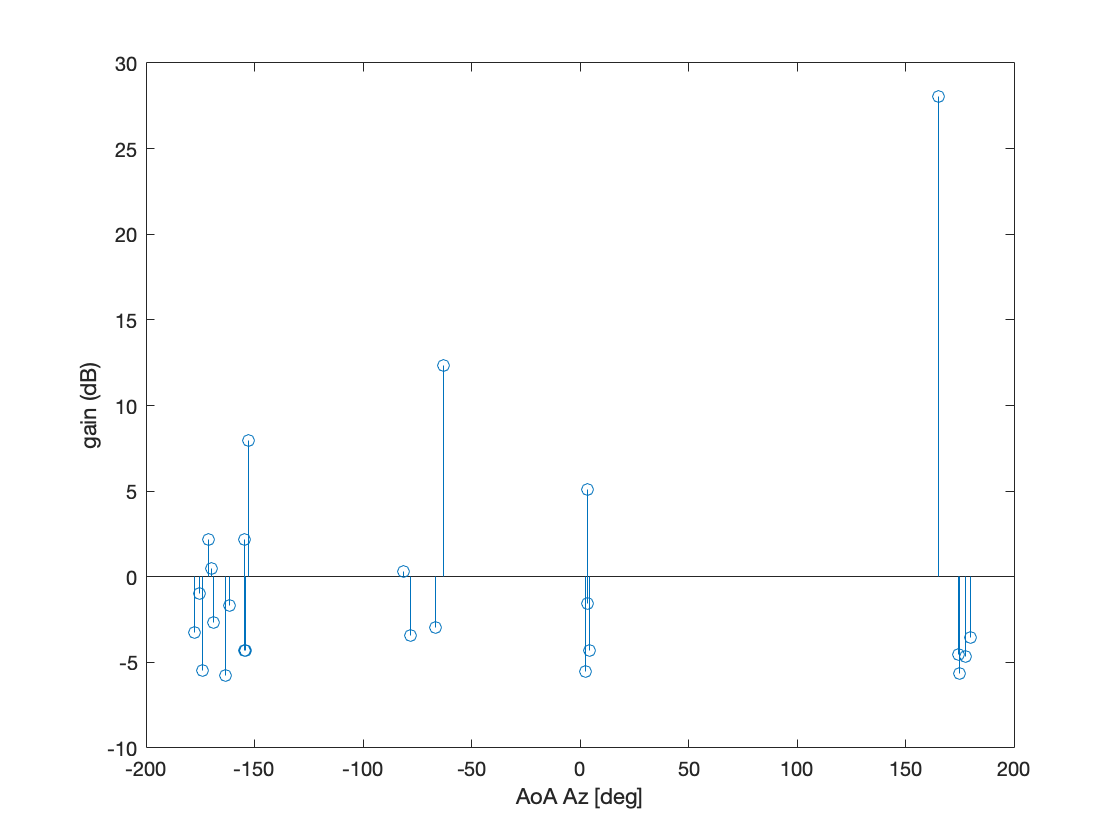

txPow = 15; %dB
nf = 7;      % Noise figure
bw = 400e6;  % Bandwidth
Ekt = -174;  % Thermal noise

%??
gain = txPow - pl'  - nf - Ekt - 10*log10(bw);

figure;
stem(aoaAz, gain);
ylabel('gain (dB)');
xlabel('AoA Az [deg]');

## Antenna Array

Demo 'mimoCapacity' has been taken into consideration. High-dimensional antenna arrays are used because of the carrier frequency. 

- TX: 4x4 URA 

- RX:  8x1 ULA

 The paths are angularly clustered so the channel has lower rank. 

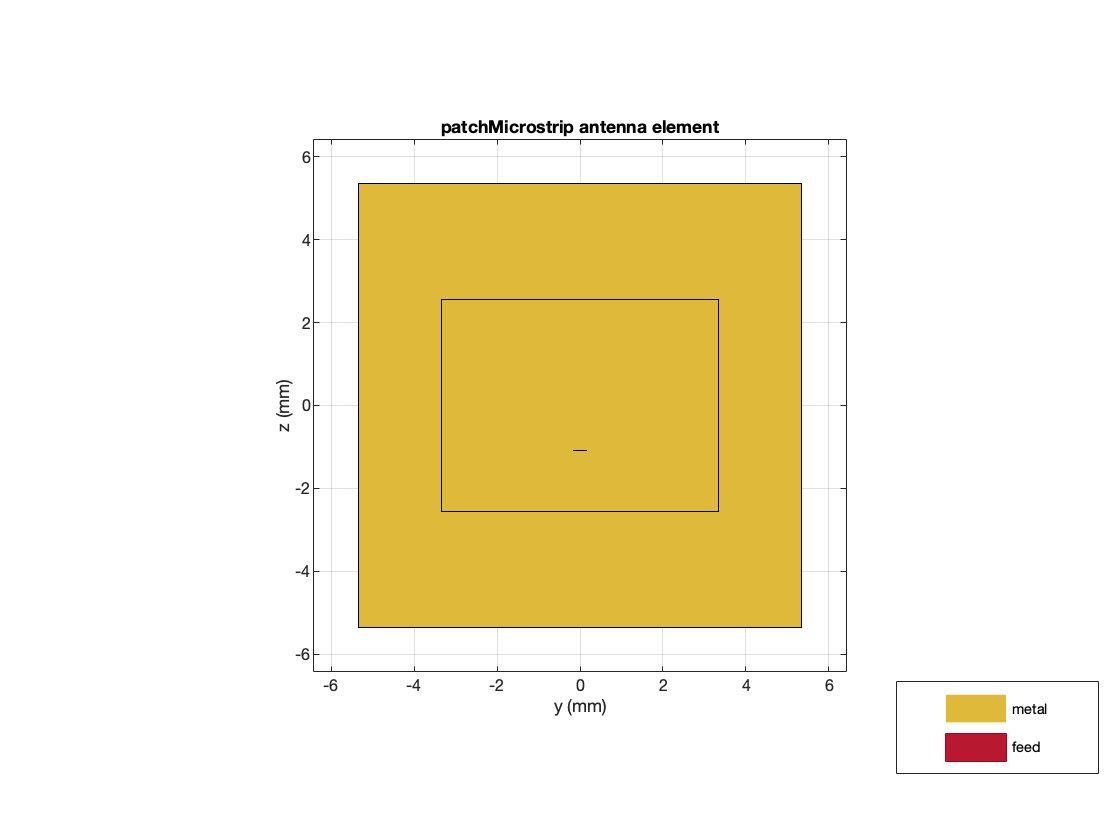

elem = design(patchMicrostrip, fc);
elem.Tilt = 90;
elem.TiltAxis = [0 1 0];
elem.show();
view(90,0)

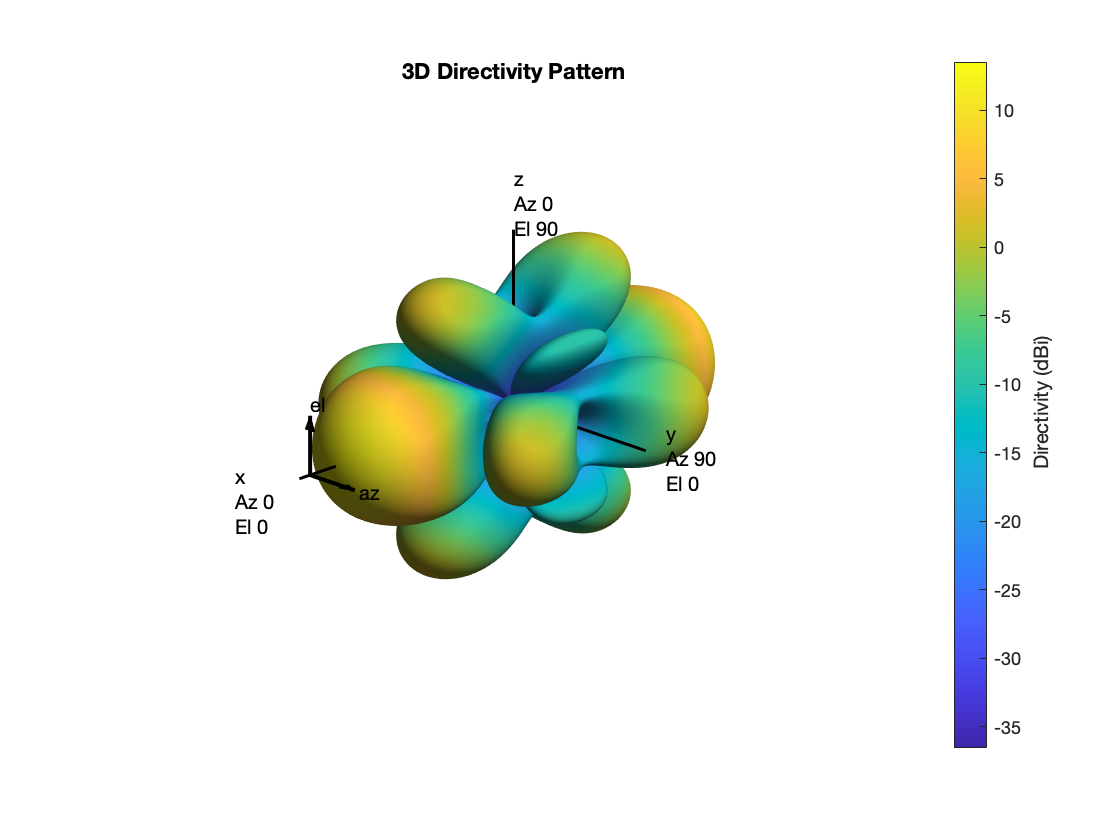

lambda = physconst('LightSpeed')/fc;

% Array parameters
dsep = 0.5*lambda;   % element spacing
nantRx = 8;          % Number of RX elements
nantTx = [4,4];      % Number of TX elements


arrRx = phased.ULA(nantRx,dsep,'ArrayAxis', 'x');
arrTx = phased.URA(nantTx,dsep,'ArrayNormal','x');

arrTx.pattern(fc)

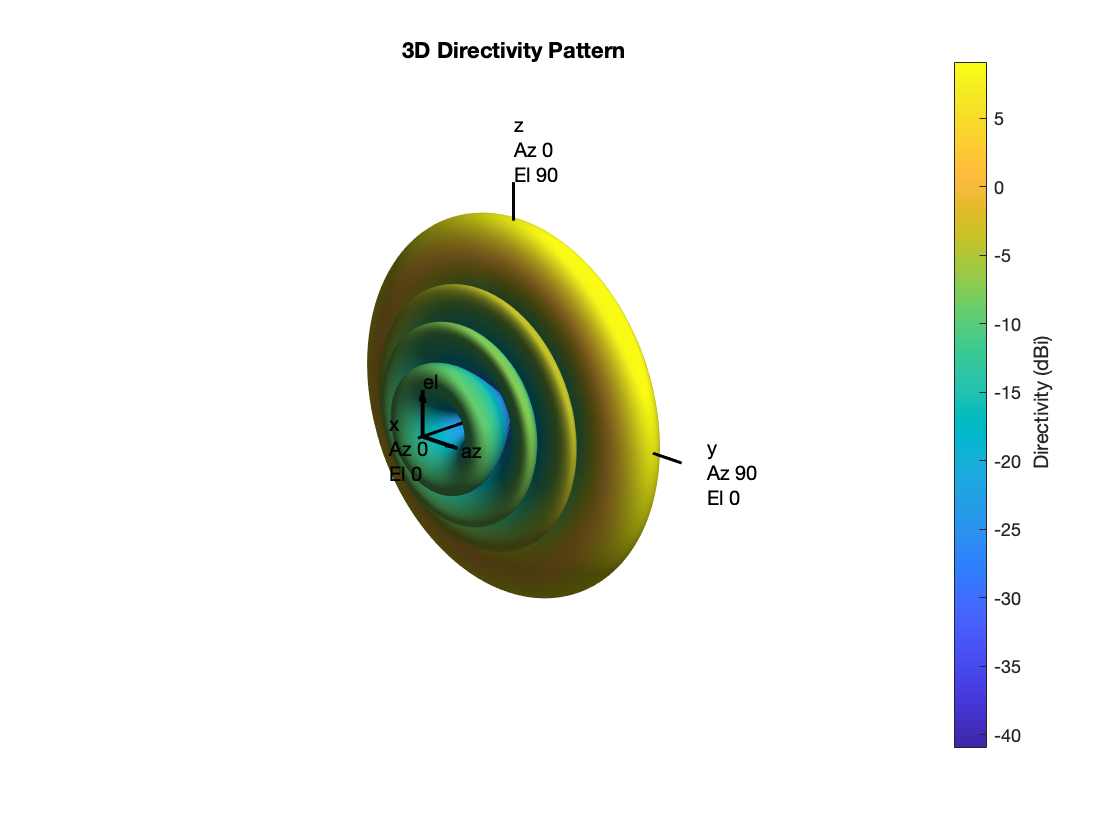

arrRx.pattern(fc)

## Array Orientation

arrPlatformTx = ArrayPlatform('elem', elem, 'arr', arrTx, 'fc', fc);
arrPlatformTx.computeNormMatrix();

arrPlatformRx =  ArrayPlatform('elem', elem, 'arr', arrRx, 'fc', fc);
arrPlatformRx.computeNormMatrix();

Following labBF: 

[svTx, elemGainTx] = arrPlatformTx.step(aodAz, aodEl, true);
[svRx, elemGainRx] = arrPlatformRx.step(aoaAz, aoaEl, true);

Gain total:

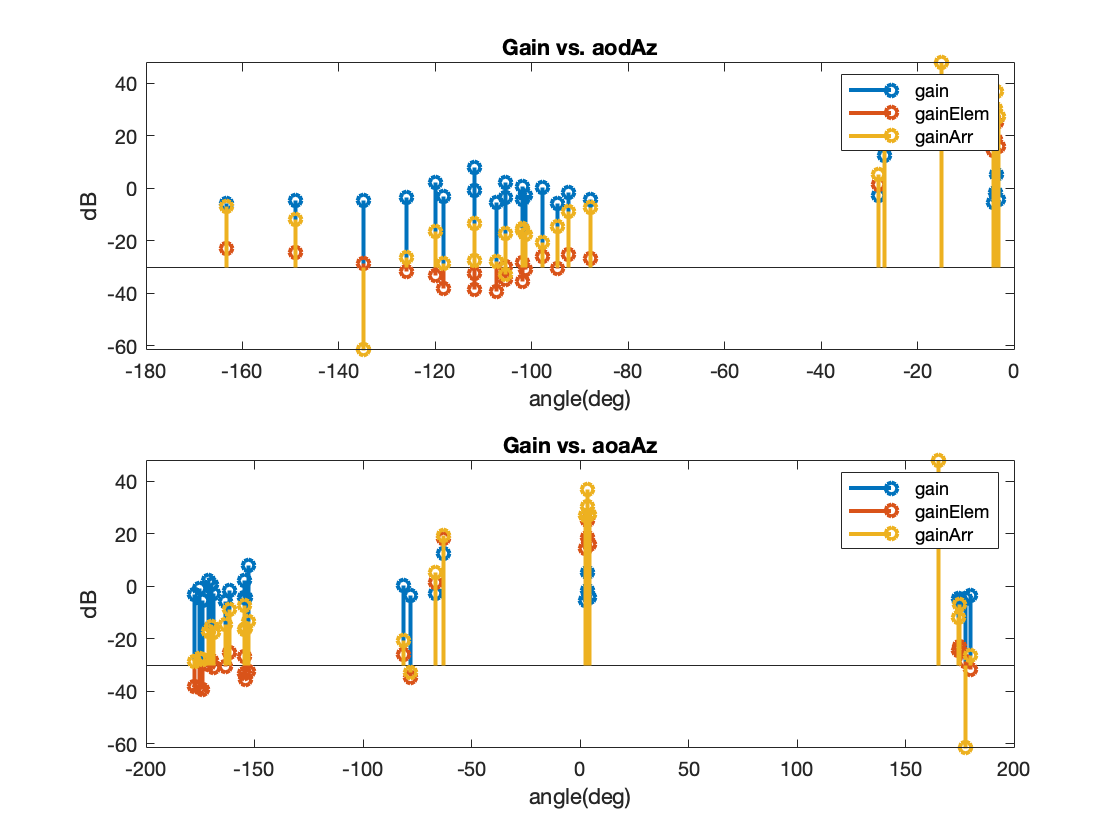

gainElem = elemGainTx + elemGainRx + gain;

[~,index] = max(gainElem);

wtx = conj(svTx(:,index)); 
wtx = wtx/ norm(wtx);
wrx = conj(svRx(:,index)); 
wrx = wrx/ norm(wrx);
arrGainTx = mag2db(abs(wtx.'*svTx))';
arrGainRx = mag2db(abs(wrx.'*svRx))';
gainArr = gain + arrGainTx + arrGainRx;


figure;

subplot(2,1,1)
stem(aodAz, gain, 'BaseValue', -30, 'LineWidth',2)
hold on
stem(aodAz, gainElem, 'BaseValue', -30, 'LineWidth',2)
hold on
stem(aodAz, gainArr, 'BaseValue', -30, 'LineWidth',2)
title('Gain vs. aodAz')
xlabel('angle(deg)')
ylabel('dB')
legend('gain', 'gainElem', 'gainArr')

subplot(2,1,2)
stem(aoaAz, gain, 'BaseValue', -30, 'LineWidth',2)
hold on 
stem(aoaAz, gainElem, 'BaseValue', -30, 'LineWidth',2)
hold on
stem(aoaAz, gainArr, 'BaseValue', -30, 'LineWidth',2)
title('Gain vs. aoaAz')
xlabel('angle(deg)')
ylabel('dB')
legend('gain', 'gainElem', 'gainArr')

## Frequency Domain Channel

The following part is followed from Beamforming lab

SubcarrierSpacing = 120;    % SCS in kHZ
NRB = 61;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB

carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

Channel for one slot:

Enoise = -5;  % Energy per noise sample in dB
fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformTx, 'rxArrPlatform', arrPlatformRx, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl,  ...
    'gain', gain, 'dly', dly, 'fc', fc, 'Enoise', Enoise);
frameNum = 0;
slotNum = 0;
[chanGrid, noiseVar] = fdchan.step(frameNum, slotNum);

Demonstration:

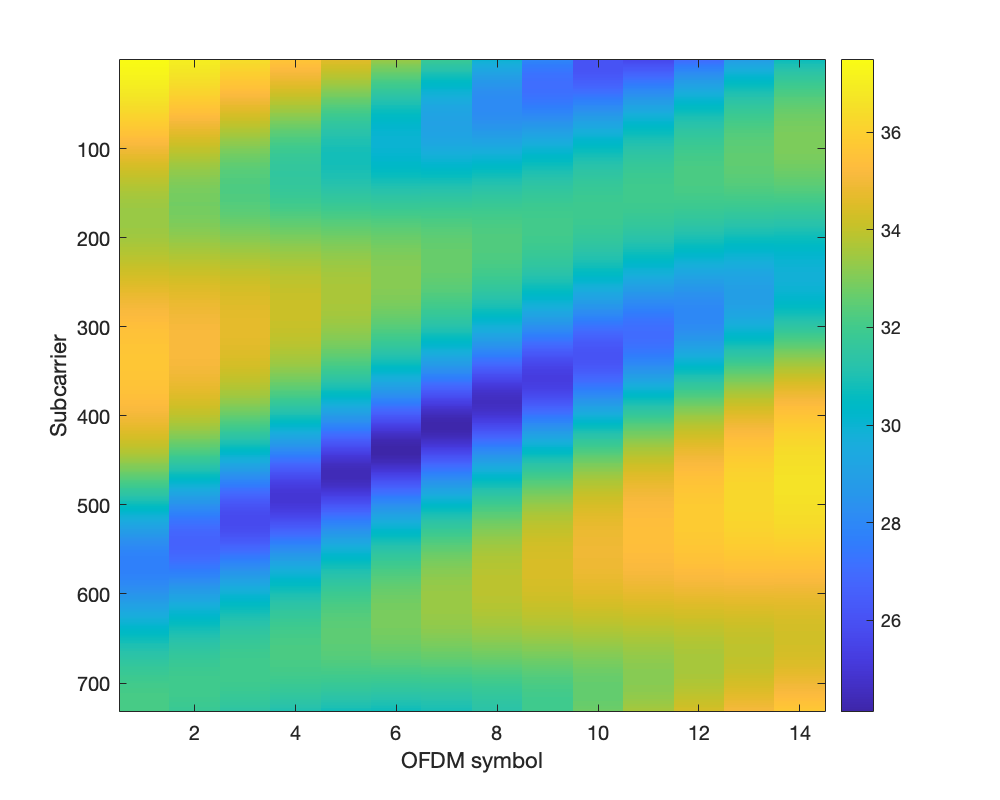

clf;
set(gcf,'Position', [0,0,500,400]);
chanGainSing = squeeze( abs(chanGrid(3,4,:,:)).^2 );
snrSing = 10*log10(chanGainSing / noiseVar);
imagesc(snrSing);
colorbar();
xlabel('OFDM symbol');
ylabel('Subcarrier');

OFDM Beamforming as like Lab8

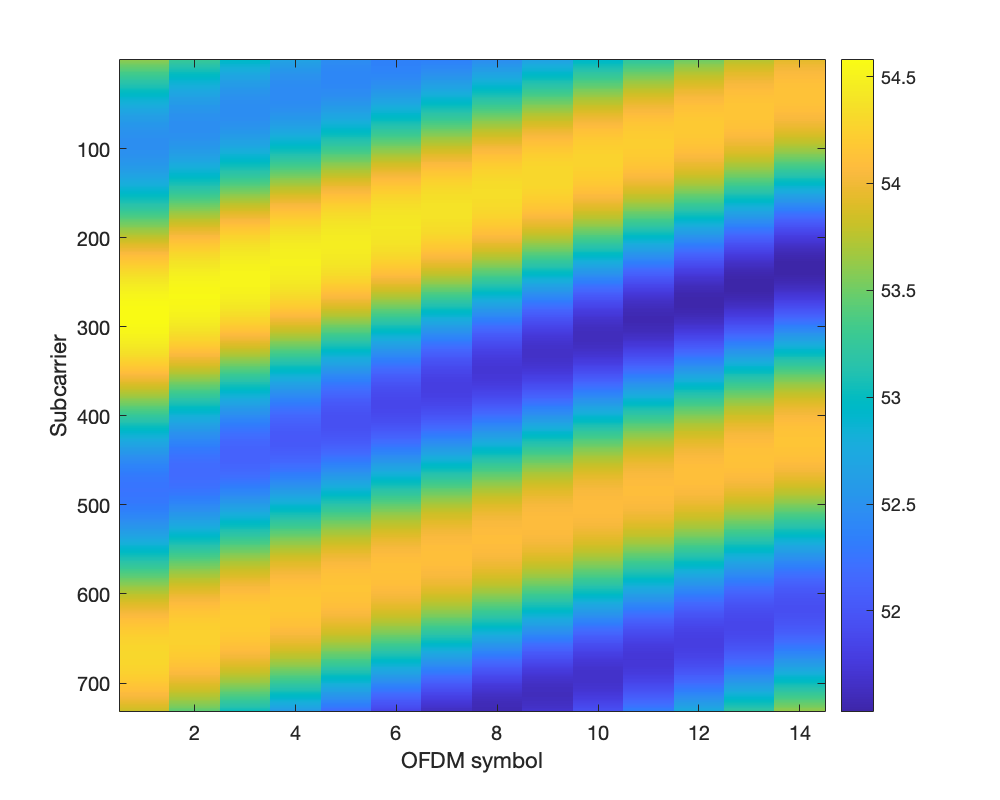

nsc = size(chanGrid,3);
nsym = size(chanGrid,4);
snrInst = zeros(nsc,nsym);
for n = 1:nsc
    for t = 1:nsym
        chani = squeeze(chanGrid(:,:,n,t));
        [wrxi,si,wtxi] = svds(chani, 1);
        
        snrInst(n, t) = pow2db(si^2/noiseVar);
    end
end

imagesc(snrInst);
colorbar();
xlabel('OFDM symbol');
ylabel('Subcarrier');